clear;
IMU_calib_data = readtable("IMU-calib-data.csv");
avg = mean(IMU_calib_data);

Gyro_static_calib = [avg.GX; avg.GY; avg.GZ]

Gyro_static_calib =     5.3328
    0.5760
   -2.2012


Accel_static_calib = [avg.AX; avg.AY; avg.AZ - 1]

Accel_static_calib =     0.0247
   -0.0092
   -0.0411


clear;
IMU_calib_data = readtable("MotorOnIMU.csv");

t = 0:0.05:19.1;

sqrt(var(IMU_calib_data))

ans = 1×6 table
      GX       GY        GZ          AX          AY          AZ   
    ______    _____    _______    ________    ________    ________

    1.5783    1.025    0.36981    0.012183    0.011967    0.010077


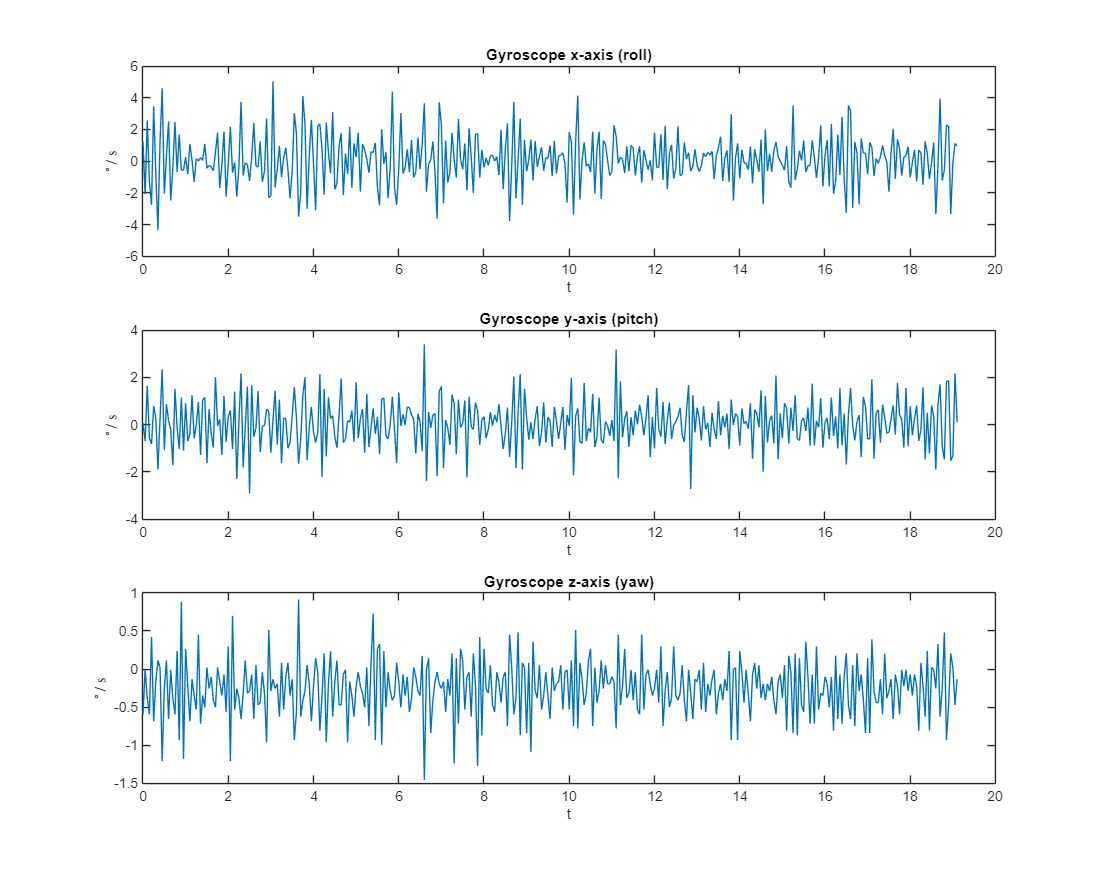


figure(Position=[0, 0, 1000,800]);
subplot(3,1,1)
plot(t, IMU_calib_data.GX)
title("Gyroscope x-axis (roll)")
ylabel("$^{\circ}$ / s", Interpreter="latex")
xlabel("t")

subplot(3,1,2)
plot(t, IMU_calib_data.GY)
title("Gyroscope y-axis (pitch)")
ylabel("$^{\circ}$ / s", Interpreter="latex")
xlabel("t")

subplot(3,1,3)
plot(t, IMU_calib_data.GZ)
title("Gyroscope z-axis (yaw)")
ylabel("$^{\circ}$ / s", Interpreter="latex")
xlabel("t")

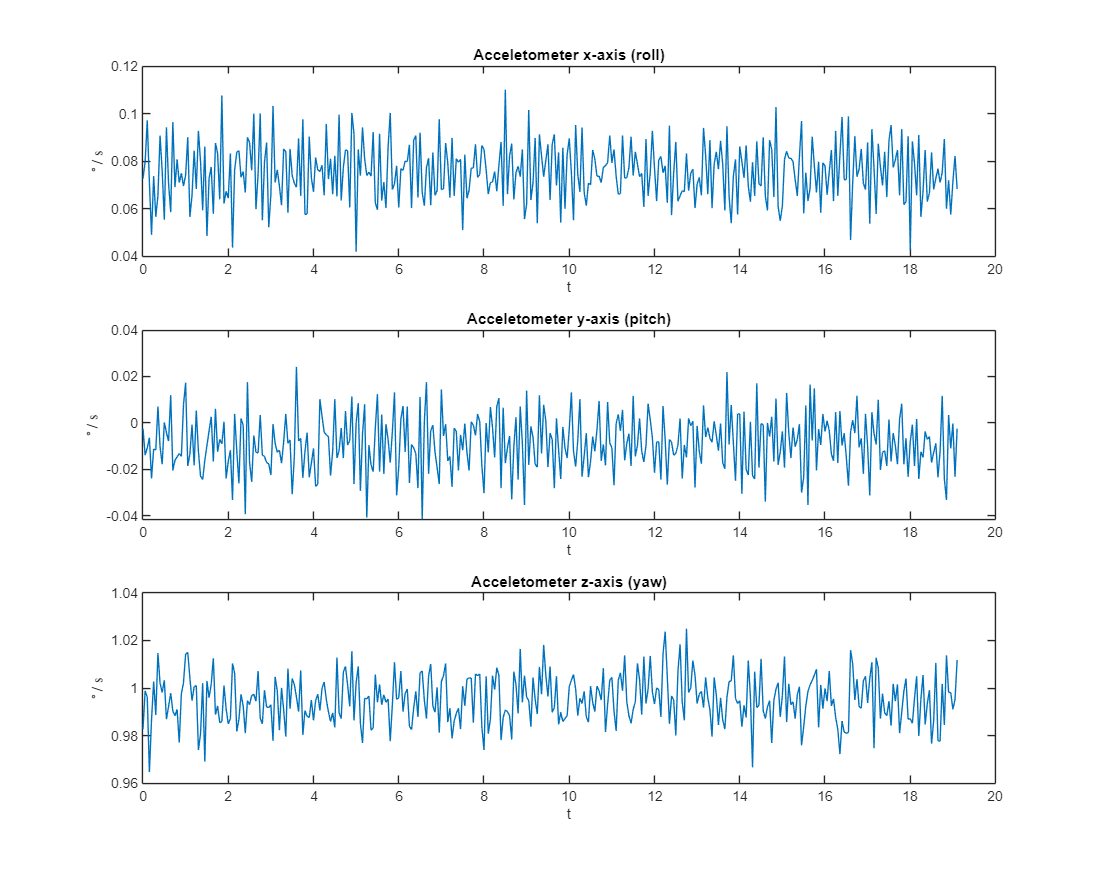

figure(Position=[0, 0, 1000,800]);
subplot(3,1,1)
plot(t, IMU_calib_data.AX)
title("Acceletometer x-axis (roll)")
ylabel("$^{\circ}$ / s", Interpreter="latex")
xlabel("t")

subplot(3,1,2)
plot(t, IMU_calib_data.AY)
title("Acceletometer y-axis (pitch)")
ylabel("$^{\circ}$ / s", Interpreter="latex")
xlabel("t")

subplot(3,1,3)
plot(t, IMU_calib_data.AZ)
title("Acceletometer z-axis (yaw)")
ylabel("$^{\circ}$ / s", Interpreter="latex")
xlabel("t")

clear;
IMU_calib_data = readtable("IMU_motor_on.csv");

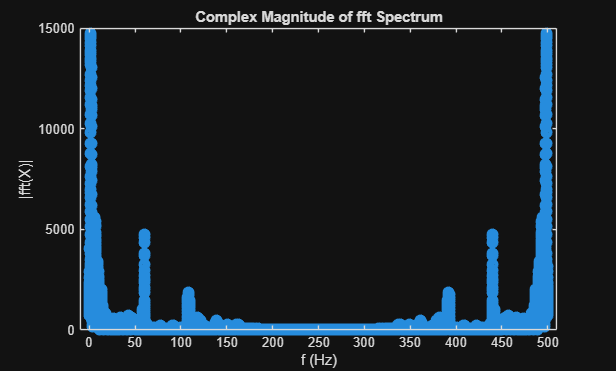

Fs = 500;                      % Sampling frequency                    
T = 1/Fs;                      % Sampling period       
L = length(IMU_calib_data.GX); % Length of signal
t = (0:L-1)*T;                 % Time vector

GX_Y = fft(IMU_calib_data.GX);

figure;
stem(Fs/L*(0:L-1),abs(GX_Y),"LineWidth",3)
title("Complex Magnitude of fft Spectrum")
xlabel("f (Hz)")
ylabel("|fft(X)|")



[b_iir, a_iir] = butter(2, 0.1, "low")

b_iir =     0.0201    0.0402    0.0201


a_iir =     1.0000   -1.5610    0.6414


b = fir1(25, 0.04, "low")

b =     0.0040    0.0051    0.0079    0.0126    0.0190    0.0269    0.0359    0.0455    0.0549    0.0635    0.0706    0.0757    0.0784    0.0784    0.0757    0.0706    0.0635    0.0549    0.0455    0.0359    0.0269    0.0190    0.0126    0.0079    0.0051    0.0040


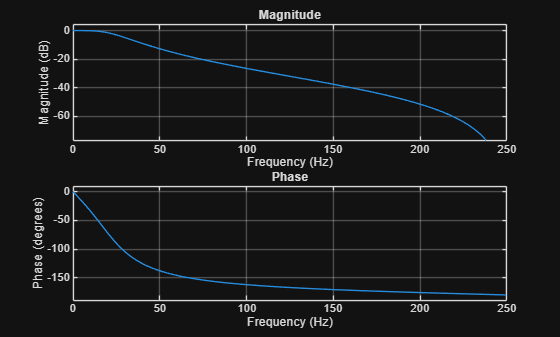

figure;
freqz(b_iir, a_iir, [], 500)

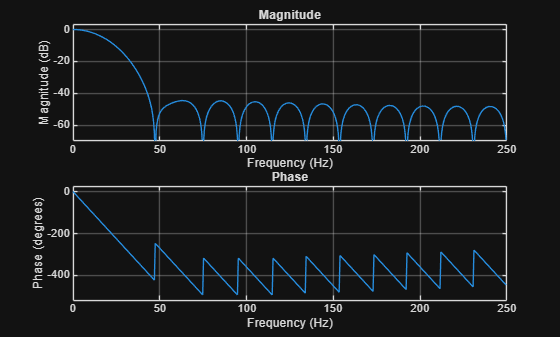

freqz(b, 1, [], 500)

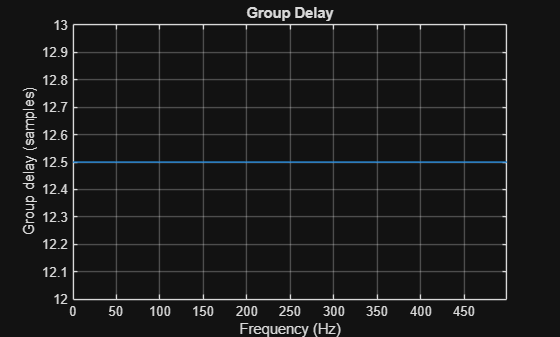

data = filter(b, 1, IMU_calib_data.GX);
data_iir = filter(b_iir, a_iir, IMU_calib_data.GX);

grpdelay(b, 1, [], "whole", 500)

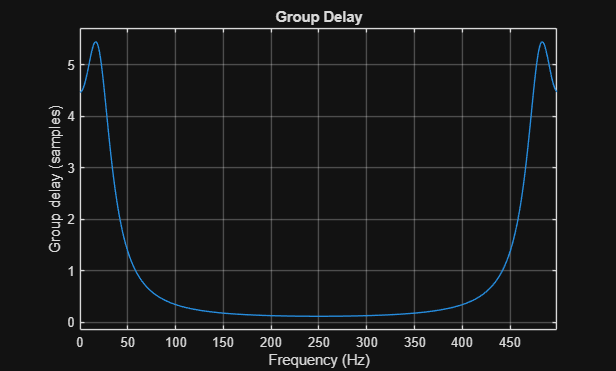

grpdelay(b_iir, a_iir, [], "whole", 500)

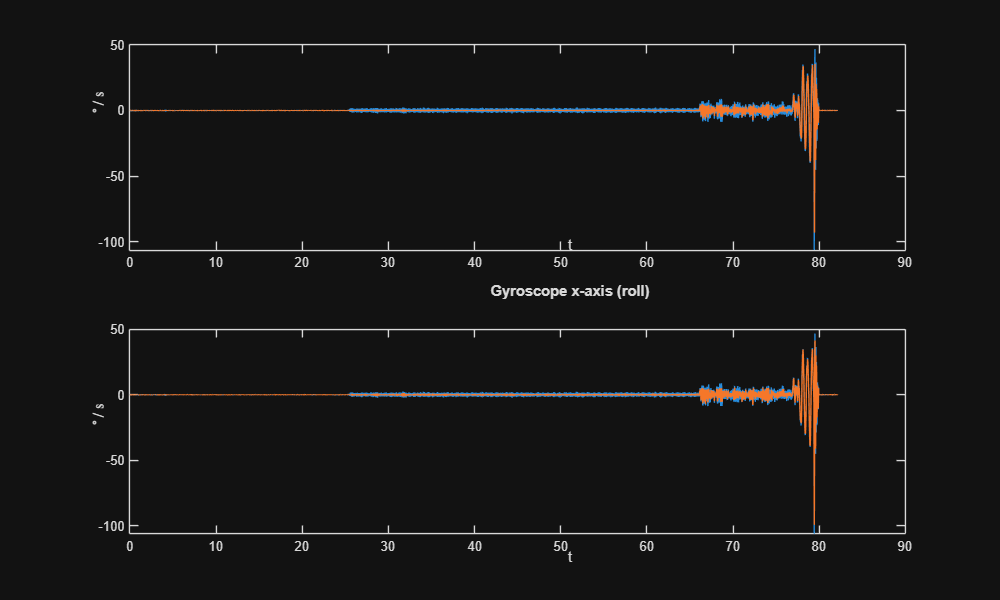


figure(Position=[0 0 1000 600]);
subplot(2,1,1)
plot(t, [IMU_calib_data.GX data])
title("Gyroscope x-axis (roll)")
ylabel("$^{\circ}$ / s", Interpreter="latex")
xlabel("t")

subplot(2,1,2)
plot(t, [IMU_calib_data.GX, data_iir])
title("Gyroscope x-axis (roll)")
ylabel("$^{\circ}$ / s", Interpreter="latex")
xlabel("t")

c_implementation = readtable("output.csv");

c_implementation = c_implementation.Var1;

err = mean(c_implementation - data_iir)

err = 3.1150e-06

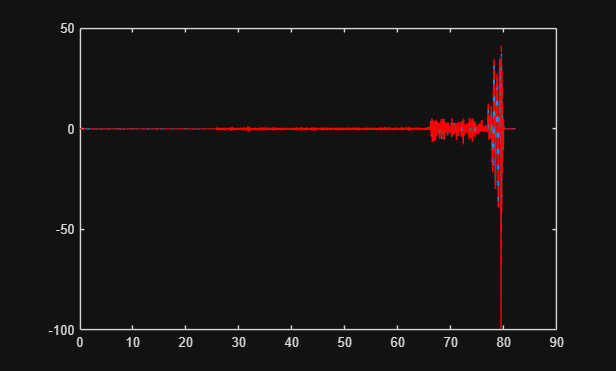


figure;
plot(t, c_implementation)
hold on;
plot(t, data_iir, "r--")